--------------------------------------------------------------


            PROBLEMAS DE VALOR INICIAL (PVI)                  


------------------------------------------------------------- 


--------------------------------------------------------------


            PROBLEMAS DE VALOR INICIAL (PVI)                  


------------------------------------------------------------- 


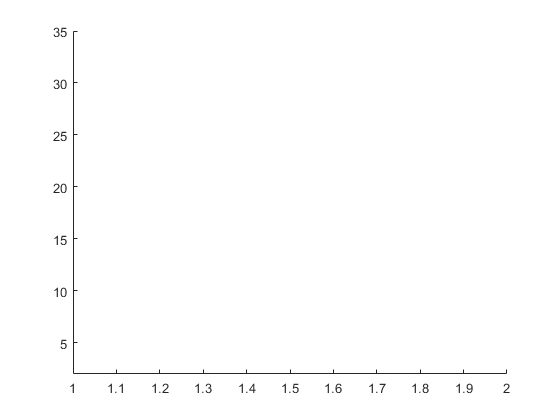

%Interface EDO/PVI
%
%   12/03/2020 - ArménioCorreia .: armenioc@isec.pt
%
%Alunos:
%   27/04/2021  Paulo Gouveia    a2020121705.isec.pt
%   27/04/2021  Miguel Ferreira  a2020107016.isec.pt
%   27/04/2021  Pablo Amaral     a2020143935.isec.pt

clear
primeiraRun=1;
menuPVI=1;
while menuPVI~=5
    clc;
    disp('--------------------------------------------------------------')
    disp('            PROBLEMAS DE VALOR INICIAL (PVI)                  ')
    disp('------------------------------------------------------------- ')
    if (~primeiraRun)
    menuPVI=menu('Métodos Numéricos para PVI',...
                 'Dados do PVI',...
                 'Solução Exata',...
                 'Solução Aproximada',...
                 'Gráficos de Resultados',...
                 'Sair');
    else
        primeiraRun=0;
        menuPVI=1;
    end
    y=[];
    switch menuPVI
        case 1
            
            while 1 %verifica se existe uma variavel simbolica(t ou y)
              strF=input('\n f(t,y) = ','s');
              f=@(t,y) eval(vectorize(strF));
              try
                  syms t y;
                  fTeste=f(t,y);
                  break;
                  
              catch me
                  errordlg('Erro! Introduza uma função em t,y','ERRO','modal');
              end
            end
                       
            while 1 %verifica se o b é escalar, real e se é maior que a
              b=str2double(input('b = ','s'));
              if(isscalar(b) && isreal(b) && b > a)
                  break;
              else
                  errordlg('Introduza um numero real b, com b > a','ERRO','modal');
              end
            end
              
        case 2
            syms y(t)
              sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0);
              g=@(t) eval(vectorize(char(sExata)));
              h=(b-a)/n;
              t=a:h:b;
              yExata=g(t);
              disp('Solução exata do PVI')
              disp(yExata)
        case 3
            y=MenuMNPVI(f,a,b,n,y0);
        case 4
            graficoRes(f,a,b,n,y0);

    end
    input('Prima numa tecla para continuar')
    
xlim([a b])
ylim([y0 35])
end